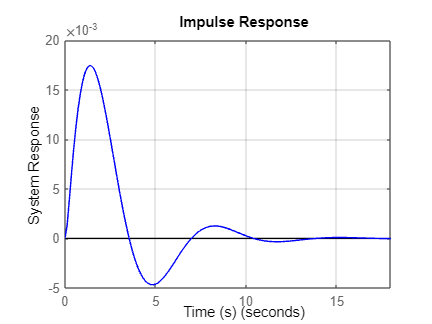

% Define system parameters
J = 0.3;  % Moment of inertia (kg*m^2)
b = 0.2;  % Damping coefficient (N*m*s/rad)
K = 0.4;    % Spring constant (N*m/rad)
setpoint = 0;  % Desired position (radians)

% Define DC motor parameters (based on the motor's rating)
V_rating = 12;   % Voltage rating (Volts)
P_rating = 100;  % Power rating (Watts)
RPM_max = 2750;  % Maximum speed (RPM)

% Calculate motor constants
Km = V_rating / (2*pi*RPM_max/60); % Back EMF constant (Volts-sec/rad)
Ke = Km; % Voltage constant (Volts-sec/rad)

% Calculate armature resistance based on power rating (P = V^2 / R)
R = V_rating^2 / P_rating; % Armature resistance (ohms)

% Initial condition for the rotational system
initial_position = deg2rad(90);  % Initial position (radians)
initial_velocity = 0;            % Initial velocity (rad/s)

% Simulation parameters
timestep = 0.01;    % Time step (s)
total_time = 25;      % Total simulation time (s)
time = 0:timestep:total_time;

% Define the transfer function of the combined system
numerator = K * Km;
denominator = [J*b, (J*R + b), (R*b + K^2 + J*b), K*R];
sys_tf = tf(numerator, denominator);

% Continue with the remaining code (simulation, control, plotting)
% Impulse Response Plot
figure;
impulse(sys_tf, 'b'); % Blue color for impulse response
xlabel('Time (s)'); % X-axis label
ylabel('System Response'); % Y-axis label
title('Impulse Response'); % Title
grid on;

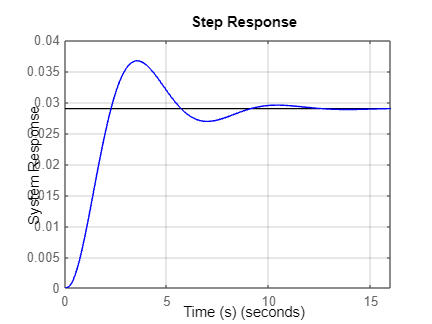


% Step Response Plot
figure;
step(sys_tf, 'b'); % Blue color for step response
xlabel('Time (s)'); % X-axis label
ylabel('System Response'); % Y-axis label
title('Step Response'); % Title
grid on;


% Compute step response of the system
[y, t] = step(sys_tf);

% Compute step response metrics
step_info = stepinfo(y, t, 'SettlingTimeThreshold', 0.05); % Settling time with 5% threshold
settling_time = step_info.SettlingTime;
overshoot = step_info.Overshoot;
rise_time = step_info.RiseTime;
display(settling_time);

settling_time = 7.8200

display(overshoot);

overshoot = 26.9307

display(rise_time);

rise_time = 1.4653

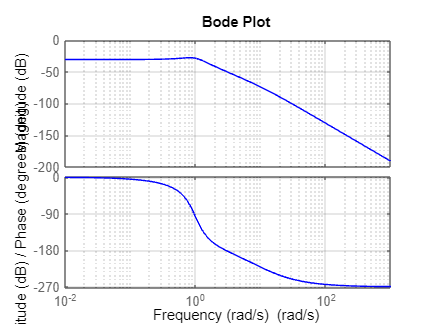


% Bode Plot
figure;
bodeplot(sys_tf, 'b'); % Blue color for Bode plot
xlabel('Frequency (rad/s)'); % X-axis label
ylabel('Magnitude (dB) / Phase (degrees)'); % Y-axis label
title('Bode Plot'); % Title
grid on;

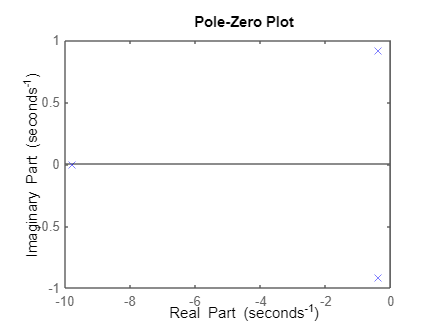


% Pole-Zero Plot
figure;
pzplot(sys_tf, 'b'); % Blue color for pole-zero plot
xlabel('Real Part'); % X-axis label
ylabel('Imaginary Part'); % Y-axis label
title('Pole-Zero Plot'); % Title

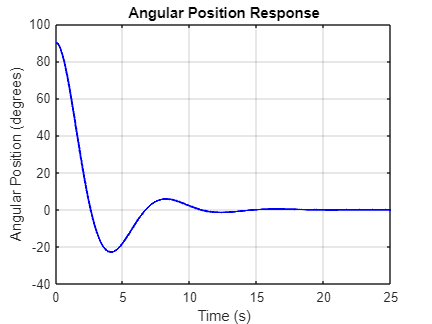


% Define the proportional gain
Kp = 5;

% Initialize variables
theta = zeros(size(time));   % Angular position
omega = zeros(size(time));   % Angular velocity
V = zeros(size(time));       % Applied voltage

% Initial condition
theta(1) = initial_position;
omega(1) = initial_velocity;

% Simulate the system with proportional control
for i = 1:length(time)-1
    % Compute error (difference between setpoint and current position)
    error = setpoint - theta(i);
    
    % Compute control action (proportional term only)
    control_action = Kp * error;
    
    % Compute applied voltage (input to the motor)
    V(i) = control_action;
    
    % Compute torque from the motor
    torque = Km * V(i);
    
    % Compute acceleration from the equation of motion
    alpha = (torque - b * omega(i)) / J;
    
    % Update velocity and position using Euler's method
    omega(i+1) = omega(i) + alpha * timestep;
    theta(i+1) = theta(i) + omega(i+1) * timestep;
end

% Plot results
figure;

plot(time, rad2deg(theta), 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Position (degrees)');
title('Angular Position Response');
grid on;

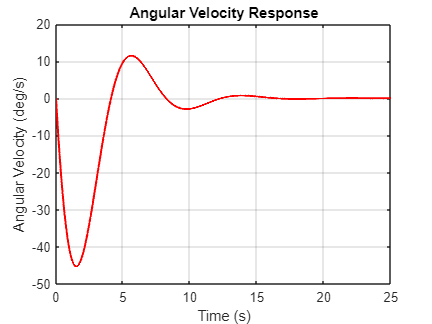



plot(time, rad2deg(omega), 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Velocity (deg/s)');
title('Angular Velocity Response');
grid on;

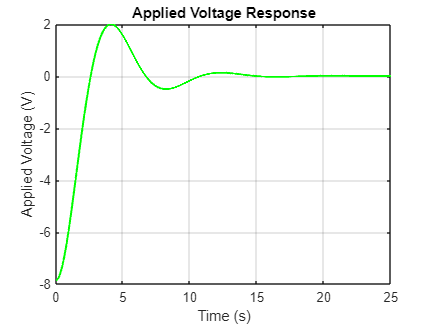



plot(time, V, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Applied Voltage (V)');
title('Applied Voltage Response');
grid on;


% Compute steady-state error for angular position response
final_position = theta(end); % Final value of the angular position
steady_state_error = setpoint - final_position;

disp(['Steady-State Error for Angular Position of ', num2str(rad2deg(initial_position)), ' degrees:']);

Steady-State Error for Angular Position of 90 degrees:


disp(steady_state_error);

  -3.9633e-04

